clear variables
close all
clc


% Choix des buckets
bucket_10 = "Simpson_dataset_10";
bucket_50 = "Simpson_dataset_50"

bucket_50 = "Simpson_dataset_50"

bucket_100 = "Simpson_dataset_100";
bucket_500="Simpson_dataset_500";
%
download_Bucket(bucket_10);
download_Bucket(bucket_50);
download_Bucket(bucket_100);
download_Bucket(bucket_500);


% 
tic
files_Bart = imageDatastore(["./"+bucket_100+"/bart_simpson","./"+bucket_100+"/bart_simpson","./"+bucket_100+"/bart_simpson"]).Files;
labels_Bart = repelem("Bart",numel(files_Bart));
t=toc;
display(t)

t = 0.3598


tic
files_Autre = imageDatastore("./"+bucket_10,'IncludeSubfolders',true).Files;
files_Autre = files_Autre(~contains(files_Autre,'simpson'));
labels_Autre = repelem("Autre",numel(files_Autre));
t=toc;
display(t)

t = 0.3029



tic
imds = imageDatastore(cat(1, files_Bart,files_Autre));
imds.Labels = categorical(cat(2,labels_Bart,labels_Autre));
t=toc;  
display(t)

t = 0.6131


numObsPerClass = countEachLabel(imds);
display(numObsPerClass)

numObsPerClass = 2×2 table
    Label    Count
    _____    _____

    Autre     350 
    Bart      300 




training_Fraction = 0.70;
[trainImds,valImds] = splitEachLabel(imds, training_Fraction);

% imageSize = [225 225 3];
% layers = [ ...
%     imageInputLayer(imageSize,'Name','input_image')
%     convolution2dLayer(3,16,'Name','conv1')
%     reluLayer('Name','relu1')
%     maxPooling2dLayer(3,'Stride',2,'Name','pool1')
%     convolution2dLayer(3,16,'Name','conv2')
%     reluLayer('Name','relu2')
%     maxPooling2dLayer(3,'Stride',2,'Name','pool2')
%     fullyConnectedLayer(21,'Name','fullyC1')
%     reluLayer('Name','relu3')
%     fullyConnectedLayer(7,'Name','fullyC2')
%     softmaxLayer('Name','sofM')
%     classificationLayer('Name','classifier')]
% Architecture = layerGraph(layers)
% %plot(Architecture)

% imageAugmenter = imageDataAugmenter( ...
%    'RandRotation',[-25 25], ...
%    'RandScale',[1 2], ...
%    'RandXTranslation',[-10 10], ...
%    'RandYTranslation',[-10 10] ...
%    );
% aug_trainImds = augmentedImageDatastore(imageSize,trainImds,"DataAugmentation",imageAugmenter);
% 
% 
% % creation d'un augmentedImageDatastore pour redimensionner la taille des images du set de validation
% aug_valImds = augmentedImageDatastore(imageSize,valImds);

netName = "darknet19";
net = eval(netName);
net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input'
                 InputSize: [256 256 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'rescale-zero-one'
    NormalizationDimension: 'auto'
                       Max: 255
                       Min: 0


imageSize = net.Layers(1).InputSize;
% La fonction isa determine si un objet est d'une certaine classe 
if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 
new_imageSize = [256, 256, 3];
%Taille image déplacée plus tôt 
% creation d'une nouvelle couche d'entrée avec la fonction imageInputLayer
% où sont spécifiés la taille en entrée, le nom de cette couche 
% (ici on propose de garder le meme nom) ; 
% en option, on garde le même type de normalisation des pixels en entrée et le
% même type de "DataAugmentation"

NewinputLayer = imageInputLayer(new_imageSize, 'Name', net.Layers(1).Name,...
    'DataAugmentation', net.Layers(1).DataAugmentation, ...
    'Normalization', net.Layers(1).Normalization);

% remplacement de la couche d'entrée avec la fonction replaceLayer où sont
% spécifiés l'architecture du réseau, le nom de la couche à remplacer, et
% la nouvelle couche
lgraph = replaceLayer(lgraph, net.Layers(1).Name, NewinputLayer);
numClasses = numel(categories(trainImds.Labels));
%numClasses=7
%
% Selon le réseau Deep Learning pré-entrainé : 
% On définit une nouvelle couche avec le nombre de classes à prédire et on
% remplace la couche désirée
% en option, on impose que les paramètres associés à cette nouvelle couche
% soient modifiés de manière plus intense par l'algorithme d'entrainement.

switch netName
     case "darknet19"  % couche de convolution 1x1 conv19
        newLearnableLayer = convolution2dLayer(1,numClasses, ...
            'Name','new_conv', ...
            'WeightLearnRateFactor',10, ...
            'BiasLearnRateFactor',10);
        lgraph = replaceLayer(lgraph,'conv19',newLearnableLayer);
     % ----    
     case "googlenet"  % couche de full-connected loss3-classifier
        newLearnableLayer = fullyConnectedLayer(numClasses, ...
            'Name','new_fc', ...
            'WeightLearnRateFactor',10, ...
            'BiasLearnRateFactor',10);
        lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
     % ----
     case "squeezenet"   % couche de convolution 1x1 conv10
        newLearnableLayer = convolution2dLayer(1,numClasses, ...
            'Name','new_conv', ...
            'WeightLearnRateFactor',10, ...
            'BiasLearnRateFactor',10);
        lgraph = replaceLayer(lgraph,'conv10',newLearnableLayer);
     % ----
end

newClassLayer = classificationLayer('Name','new_classoutput');

switch netName
     case "darknet19"           
        lgraph = replaceLayer(lgraph,'output',newClassLayer);         
     case "googlenet"  
        lgraph = replaceLayer(lgraph,'output',newClassLayer);
     case "squeezenet"   
        lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);
end
new_imageSize = [256, 256, 3];
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

augimdsTrain = augmentedImageDatastore(new_imageSize,trainImds);
augimdsValidation = augmentedImageDatastore(new_imageSize,valImds);

miniBatchSize = 64;
%valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',3, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',1, ...
    'ValidationPatience',3,...
    'Verbose',true, ...                %     'Verbose',false, ...
    'Plots',"none", ...                %     'Plots','training-progress', ...
    'ExecutionEnvironment',"auto");    %     'ExecutionEnvironment',"parallel");


tic; 
    net = trainNetwork(augimdsTrain,lgraph,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:19 |       51.56% |       50.26% |       1.1534 |       1.3935 |      1.0000e-04 |
|       1 |           2 |       00:04:13 |       57.81% |       49.74% |       1.2709 |       1.2797 |      1.0000e-04 |
|       1 |           3 |       00:05:38 |       53.13% |       53.85% |       1.0308 |       1.1561 |      1.0000e-04 |
|       1 |           4 |       00:07:16 |       64.06% |       55.90% |       0.8668 |   

tmps = toc

tmps = 1.9403e+03

%netDL = trainNetwork(aug_trainImds, Architecture, options)
save("net_Bart.mat","net");
%Prédictions

%imresize(valImds,[256,256,3]);
Predictions = classify(net,augimdsValidation);
%sTaux d'images bien classées
TauxBienClasse = sum(valImds.Labels==Predictions)/numel(Predictions)

TauxBienClasse = 0.9692

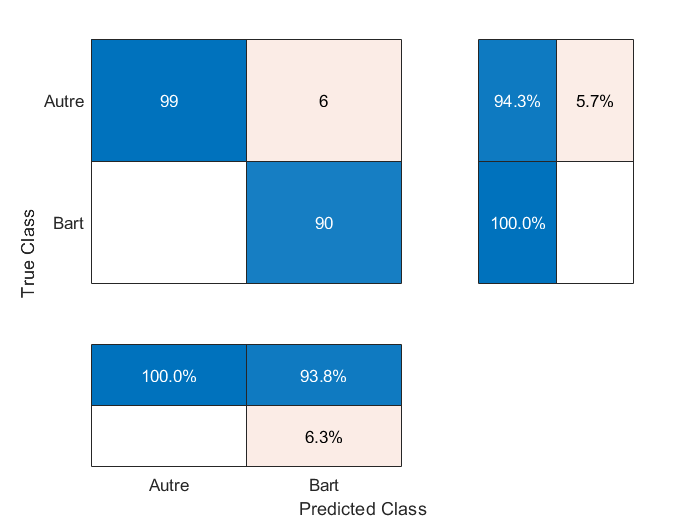

%Calcul de la matrice de confusion
confusionchart(valImds.Labels,Predictions,'ColumnSummary','column-normalized', 'RowSummary','row-normalized');

function download_Bucket(bucketName)
    %
    tic;
    if ~exist(bucketName,"dir")
        nomFichier=bucketName+".zip";
        % les fichiers sont disponibles à cette adresse web :
        dataURL = 'https://perso.imt-mines-albi.fr/~baillon/DATAS/';
        unzip(dataURL + "IMG/" + nomFichier);
        t=toc;
        fprintf("téléchargement de %s ["+t+"s]\n",bucketName);
    end
end